cd(fileparts(matlab.desktop.editor.getActiveFilename))
close all; clearvars; clc

cd("../data-engineering")
load("../../temp-data/participant_list.mat")
cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Performance Metric Computation

metric_type = "trmse";
metric_task = "none";
y = compute_performance_table(participant_array, metric_type, metric_task);

Participant 01: P05
	Condition: par
		Task: ml
			Trial 01	Co-Activation:0.429	 Differentiation:0.144
			Trial 02	Co-Activation:0.470	 Differentiation:0.252
			Trial 03	Co-Activation:0.470	 Differentiation:0.287
			Trial 04	Co-Activation:0.417	 Differentiation:0.329
			Trial 05	Co-Activation:0.418	 Differentiation:0.315
			Trial 06	Co-Activation:0.457	 Differentiation:0.172
			Trial 07	Co-Activation:0.394	 Differentiation:0.231
			Trial 08	Co-Activation:0.385	 Differentiation:0.147
			Trial 09	Co-Activation:0.343	 Differentiation:0.285
		Task: hl
			Trial 01	Co-Activation:0.444	 Differentiation:0.110
			Trial 02	Co-Activation:0.322	 Differentiation:0.112
			Trial 03	Co-Activation:0.319	 Differentiation:0.144
			Trial 04	Co-Activation:0.245	 Differentiation:0.120
			Trial 05	Co-Activation:0.246	 Differentiation:0.179
			Trial 06	Co-Activation:0.274	 Differentiation:0.045
			Trial 07	Co-Activation:0.273	 Differentiation:0.057
			Trial 08	Co-Activation:0.380	 Differentiation:0.140
			Tria

## Statistical Analysis

### Step 0. Structure Data Matrix

Between-factors (Hand Condition) are specified in the rows of `y_between`. Within-subject factors (Task, Gesture Type, and Trial Count) are specified in `y_within` and they are the labels for each column of `y_between`.

y_between = y

y_between = 15 55 table
    b_condition      y_1        y_2        y_3        y_4        y_5        y_6        y_7        y_8        y_9        y_10        y_11        y_12       y_13        y_14       y_15       y_16       y_17       y_18       y_19       y_20       y_21       y_22       y_23       y_24       y_25       y_26       y_27       y_28       y_29       y_30        y_31       y_32        y_33        

w_task = [repmat("Machine Learning", 18,1); repmat("Human Learning", 18,1); repmat("Co-Adaptive Learning", 18, 1)];
w_gesture = repmat([repmat("Co-Activation", 9,1); repmat("Differentiation", 9,1)], 3,1);
w_trial = repmat((1:9)', 6,1);
y_within = table(w_task, w_gesture, w_trial)

y_within = 54 3 table
          w_task              w_gesture        w_trial
    __________________    _________________    _______

    "Machine Learning"    "Co-Activation"         1   
    "Machine Learning"    "Co-Activation"         2   
    "Machine Learning"    "Co-Activation"         3   
    "Machine Learning"    "Co-Activation"         4   
    "Machine Learning"    "Co-Activation"         5   
    "Machine Learning"    "Co-Activation"         6   
    "Machine Learning"    "Co-Activation"         7   
    "Machine Learning"    "Co-Activation"         8   
    "Machine Learning"    "Co-Activation"         9   
    "Machine Learning"    "Differentiation"       1   
    "Machine Learning"    "Differentiation"       2   
    "Machine Learning"    "Differentiation"       3   
    "Machine Learning"    "Differentiation"       4   
    "Machine Learning"    "Differentiation"       

y.participant_id = [1;1;2;2;3;3;4;4;5;5;6;7;8;9;10]

y = 15 56 table
    b_condition      y_1        y_2        y_3        y_4        y_5        y_6        y_7        y_8        y_9        y_10        y_11        y_12       y_13        y_14       y_15       y_16       y_17       y_18       y_19       y_20       y_21       y_22       y_23       y_24       y_25       y_26       y_27       y_28       y_29       y_30        y_31       y_32        y_33        y_34

tbl = stack(y, 2:55)

tbl = 810 4 table
    b_condition    participant_id    y_1_y_2_y_3_y_4_y_5_y_6_y_7_y_8_y_9_y_10_y_11_y_12_y_13_y_14__1    y_1_y_2_y_3_y_4_y_5_y_6_y_7_y_8_y_9_y_10_y_11_y_12_y_13_y_14_y_
    ___________    ______________    _______________________________________________________________    _______________________________________________________________

       "par"             1                                        y_1                                                               0.42876                            
       "par"             1                                        y_2                                                               0.46986                            
       "par"             1                                        y_3                                                               0.46987                            
     

tbl.Properties.VariableNames = ["Neurological Condition","Participant ID", "Temp Trial ID", "Gesture RMSE"]

tbl = 810 4 table
    Neurological Condition    Participant ID    Temp Trial ID    Gesture RMSE
    ______________________    ______________    _____________    ____________

            "par"                   1               y_1            0.42876   
            "par"                   1               y_2            0.46986   
            "par"                   1               y_3            0.46987   
            "par"                   1               y_4            0.41732   
            "par"                   1               y_5            0.41752   
            "par"                   1               y_6            0.45718   
            "par"                   1               y_7            0.39423   
            "par"                   1               y_8            0.38462   
            "par"                   1               y_9          

tbl = [tbl,repmat(y_within,15,1)]

tbl = 810 7 table
    Neurological Condition    Participant ID    Temp Trial ID    Gesture RMSE          w_task              w_gesture        w_trial
    ______________________    ______________    _____________    ____________    __________________    _________________    _______

            "par"                   1               y_1            0.42876       "Machine Learning"    "Co-Activation"         1   
            "par"                   1               y_2            0.46986       "Machine Learning"    "Co-Activation"         2   
            "par"                   1               y_3            0.46987       "Machine Learning"    "Co-Activation"         3   
            "par"                   1               y_4            0.41732       "M

tbl = renamevars(tbl, ["w_task", "w_gesture", "w_trial"], ["Decoder Type", "Gesture Type", "Trial ID"])

tbl = 810 7 table
    Neurological Condition    Participant ID    Temp Trial ID    Gesture RMSE       Decoder Type         Gesture Type       Trial ID
    ______________________    ______________    _____________    ____________    __________________    _________________    ________

            "par"                   1               y_1            0.42876       "Machine Learning"    "Co-Activation"         1    
            "par"                   1               y_2            0.46986       "Machine Learning"    "Co-Activation"         2    
            "par"                   1               y_3            0.46987       "Machine Learning"    "Co-Activation"         3    
            "par"                   1               y_4            0.41732    

tbl = tbl(:, ["Participant ID", "Neurological Condition", "Decoder Type", "Trial ID", "Gesture Type", "Gesture RMSE"])

tbl = 810 6 table
    Participant ID    Neurological Condition       Decoder Type       Trial ID      Gesture Type       Gesture RMSE
    ______________    ______________________    __________________    ________    _________________    ____________

          1                   "par"             "Machine Learning"       1        "Co-Activation"        0.42876   
          1                   "par"             "Machine Learning"       2        "Co-Activation"        0.46986   
          1                   "par"             "Machine Learning"       3        "Co-Activation"        0.46987   
          1                   "par"             "Machine Learning"       4        "Co-Activation"        0.41732   
          1                   "par"             "Machine Learning"       5       

par_idxs = tbl.("Neurological Condition") == "par";
tbl.("Neurological Condition")(par_idxs) = "Paretic"

tbl = 810 6 table
    Participant ID    Neurological Condition       Decoder Type       Trial ID      Gesture Type       Gesture RMSE
    ______________    ______________________    __________________    ________    _________________    ____________

          1                 "Paretic"           "Machine Learning"       1        "Co-Activation"        0.42876   
          1                 "Paretic"           "Machine Learning"       2        "Co-Activation"        0.46986   
          1                 "Paretic"           "Machine Learning"       3        "Co-Activation"        0.46987   
          1                 "Paretic"           "Machine Learning"       4        "Co-Activation"        0.41732   
          1                 "Paretic"           "Machine Learning"       5       

xpar_idxs = tbl.("Neurological Condition") == "xpar";
tbl.("Neurological Condition")(xpar_idxs) = "Nonparetic";
hlt_idxs = tbl.("Neurological Condition") == "hlt";
tbl.("Neurological Condition")(hlt_idxs) = "Healthy"

tbl = 810 6 table
    Participant ID    Neurological Condition       Decoder Type       Trial ID      Gesture Type       Gesture RMSE
    ______________    ______________________    __________________    ________    _________________    ____________

          1                 "Paretic"           "Machine Learning"       1        "Co-Activation"        0.42876   
          1                 "Paretic"           "Machine Learning"       2        "Co-Activation"        0.46986   
          1                 "Paretic"           "Machine Learning"       3        "Co-Activation"        0.46987   
          1                 "Paretic"           "Machine Learning"       4        "Co-Activation"        0.41732   
          1                 "Paretic"           "Machine Learning"       5       

tbl.("Neurological Condition") = categorical(tbl.("Neurological Condition"), {'Paretic', 'Nonparetic', 'Healthy'}, "Ordinal",true);
tbl.("Decoder Type") = categorical(tbl.("Decoder Type"), {'Machine Learning', 'Co-Adaptive Learning', 'Human Learning'}, "Ordinal",true);
tbl.("Gesture Type") = categorical(tbl.("Gesture Type"), {'Co-Activation', 'Differentiation'}, "Ordinal",true)

tbl = 810 6 table
    Participant ID    Neurological Condition      Decoder Type      Trial ID     Gesture Type      Gesture RMSE
    ______________    ______________________    ________________    ________    _______________    ____________

          1                  Paretic            Machine Learning       1        Co-Activation        0.42876   
          1                  Paretic            Machine Learning       2        Co-Activation        0.46986   
          1                  Paretic            Machine Learning       3        Co-Activation        0.46987   
          1                  Paretic            Machine Learning       4        Co-Activation        0.41732   
          1                  Paretic            Machine Learning       5        Co-Activation        0.41

long_tbl = sortrows(tbl, {'Participant ID', 'Neurological Condition', 'Decoder Type', 'Trial ID', 'Gesture Type'})

long_tbl = 810 6 table
    Participant ID    Neurological Condition      Decoder Type      Trial ID     Gesture Type      Gesture RMSE
    ______________    ______________________    ________________    ________    _______________    ____________

          1                  Paretic            Machine Learning       1        Co-Activation        0.42876   
          1                  Paretic            Machine Learning       1        Differentiation      0.14351   
          1                  Paretic            Machine Learning       2        Co-Activation        0.46986   
          1                  Paretic            Machine Learning       2        Differentiation      0.25239   
          1                  Paretic            Machine Learning       3        Co-Activation       

writetable(long_tbl, '../../results/long-tables/rmse_raw.csv','WriteMode','overwrite')

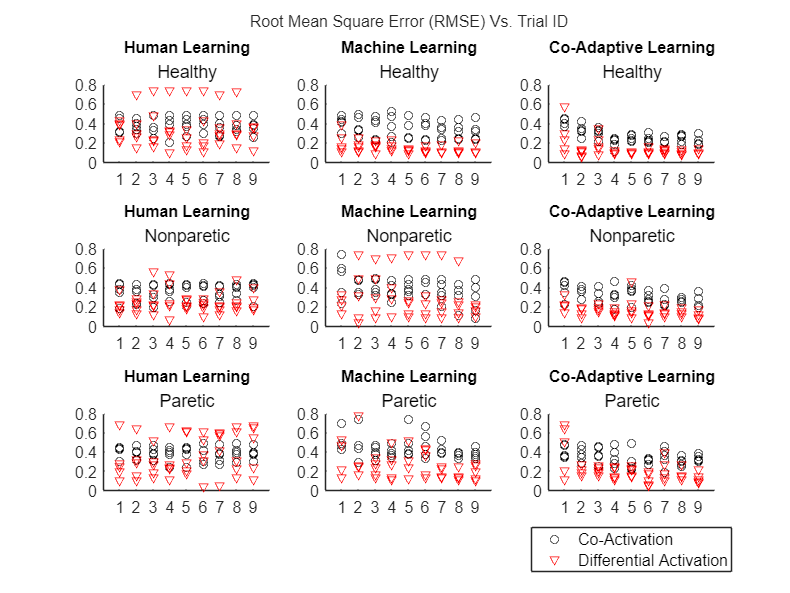

fig_h = figure;
set(fig_h, 'Renderer', 'painters');
set(fig_h, "Units","inches", "Position", [6, 3, 10, 7.5])%PPT

tlo = tiledlayout('flow');
for neuro_cond = ["Healthy", "Nonparetic", "Paretic"]
for decoder_type = ["Human Learning", "Machine Learning", "Co-Adaptive Learning"]
cond_idxs = and(tbl.("Neurological Condition") == neuro_cond, tbl.("Decoder Type") == decoder_type);
ax = nexttile;
hold on
gesture_type = "Co-Activation";
coact_idxs = and(cond_idxs, tbl.("Gesture Type") == gesture_type);
plot_tbl = tbl(coact_idxs, {'Trial ID', 'Gesture RMSE'});
plot(plot_tbl.("Trial ID"), plot_tbl.("Gesture RMSE"), 'ko')

gesture_type = "Differentiation";
diffact_idxs = and(cond_idxs, tbl.("Gesture Type") == gesture_type);
plot_tbl = tbl(diffact_idxs, {'Trial ID', 'Gesture RMSE'});
plot(plot_tbl.("Trial ID"), plot_tbl.("Gesture RMSE"), 'rv')
hold off
title(ax, decoder_type)
subtitle(ax, neuro_cond)
ylim([0, 0.8])
xlim([0 10])
xticks(1:9)
yticks(0:0.2:0.8)
box off
end
end
title(tlo, "Root Mean Square Error (RMSE) Vs. Trial ID")
legend(ax, ["Co-Activation", "Differential Activation"], 'Location', 'southoutside')
fontsize(fig_h, 12,"points")%PPT

### Step 1. Visualize Raw Data in Panels

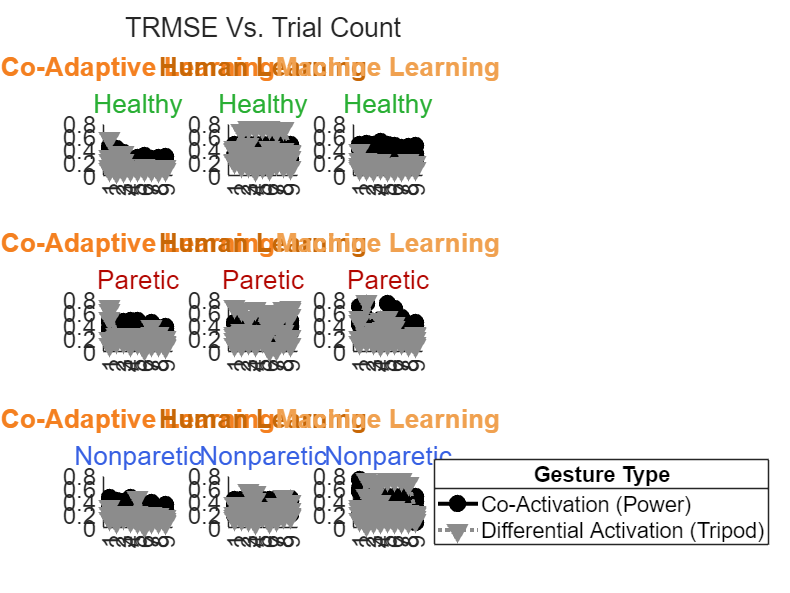

tlo = tiledlayout('flow');
fontsize(tlo, 20, "points")
% tlo.Units = 'inches';
% tlo.OuterPosition = [0 0 17 10.5];
ax_handle_list = [];
for cond = ["hlt","par", "xpar"]
    y_cond = y_between(y_between.b_condition==cond,2:end);
    for task = ["Co-Adaptive Learning", "Human Learning", "Machine Learning"]
        y_coact = y_cond(:, and(y_within.w_task == task, y_within.w_gesture == "Co-Activation"));
        y_diffact = y_cond(:, and(y_within.w_task == task, y_within.w_gesture == "Differentiation"));
        ax_handle = nexttile;
        ax_handle_list = [ax_handle_list, ax_handle];
        hold on
        plot(y_coact{:,:}', '-ok', 'MarkerFaceColor','k', 'LineWidth',3,'MarkerSize',10 )
        plot(y_diffact{:,:}', ':v', 'MarkerFaceColor',"#8c8c8c", 'LineWidth',3,'MarkerSize',10, 'Color',"#8c8c8c")
        hold off
        title(task)
        switch task
            case "Machine Learning"
                title(task, 'Color', "#f0a150")
            case "Human Learning"
                title(task, 'Color', "#c76706")
            case "Co-Adaptive Learning"
                title(task, 'Color', "#f48020")
        end
        switch cond
            case "par"
                subtitle("Paretic", 'Color', "#b30600")
            case "xpar"
                subtitle("Nonparetic", 'Color', "#3760e3")
            case "hlt"
                subtitle("Healthy", 'Color', "#29af34")
        end
        xticks(1:9)
        yticks(0:0.2:0.8)
    end
end
legend_handle = legend(["Co-Activation (Power)",repmat("",1,4), "Differential Activation (Tripod)"], "Location","eastoutside");
title(legend_handle, "Gesture Type")
linkaxes(ax_handle_list, 'xy')
ylim([0, 0.8])
xlim([0 10])
title(tlo, sprintf("%s Vs. Trial Count", upper(metric_type)))
set(ax_handle_list, 'FontSize', 18)

save("..\..\results\trmse_raw.mat", "y_between", "y_within")

fig_h = figure;
set(fig_h, 'Renderer', 'painters');
set(fig_h, "Units","centimeters", "Position", [5, 5, 18.2, 11.25])
fontsize(fig_h, 8,"points")
% legend(plt_h, "Paretic", "Non-Paretic", "Healthy")
ylabel("Change in Performance (\Delta RMSE)")
title("Learning Effect")
cond = "hlt"
y_cond = y_between(y_between.b_condition==cond,2:end);
task = "Co-Adaptive Learning"
y_coact = y_cond(4, and(y_within.w_task == task, y_within.w_gesture == "Co-Activation"));
y_diffact = y_cond(4, and(y_within.w_task == task, y_within.w_gesture == "Differentiation"));
ax_handle = nexttile;
ax_handle_list = [ax_handle_list, ax_handle];
hold on
% plot(y_diffact{:,:}', ':v', 'MarkerFaceColor',"#8c8c8c", 'LineWidth',3,'MarkerSize',10, 'Color',"#8c8c8c")
[model_fit, model_gof] = fit((1:9)',y_coact{:,:}',"exp1", 'StartPoint', [0.6, -0.2]);
param_fit_arr = model_fit.b;
plot(model_fit, (1:9)', y_coact{:,:}', '-ko')
hold off
xticks(1:1:9)
xlim([0.5,9.5])
yticks(0:0.1:0.5)
ylim([0, 0.5])
title(task)
ytickformat('%0.1f')

print(fig_h, '../../results/eps-figs/def-rmse', '-depsc', '-r600', '-vector')

### Step 3. Fit Repeated Measures Model

rm = fitrm(y_between, 'y_1-y_54~b_condition', "WithinDesign",y_within)
rm.Coefficients
rm.Covariance

### RANOVA on the Repeated Measures Model

ranova_tbl = ranova(rm, "WithinModel", "w_task + w_trial + w_trial*w_task")
multcompare(rm, "b_condition")
multcompare(rm, "w_task")
multcompare(rm, "w_trial")

### Export to R

r_dataframe = [];
for i=1:height(y_between)
    if or(y_between{i,1} == "par", y_between{i,1} == "xpar")
        p_id = i+mod(i,2);
    else
        p_id = i;
    end
    p_tbl = array2table([y_between{i,2:end}', repmat(p_id, height(y_within),1), repmat(y_between{i,1}, height(y_within),1), y_within{:,:}], ...
        "VariableNames", ["rmse", "p_id", "p_cond", "task_type", "gesture_type", "trial_num"]);
    r_dataframe = [r_dataframe; p_tbl];
end

r_dataframe

r_dataframe = 810 6 table
      rmse       p_id    p_cond        task_type           gesture_type       trial_num
    _________    ____    ______    __________________    _________________    _________

    "0.42876"    "2"     "par"     "Machine Learning"    "Co-Activation"         "1"   
    "0.46986"    "2"     "par"     "Machine Learning"    "Co-Activation"         "2"   
    "0.46987"    "2"     "par"     "Machine Learning"    "Co-Activation"         "3"   
    "0.41732"    "2"     "par"     "Machine Learning"    "Co-Activation"         "4"   
    "0.41752"    "2"     "par"     "Machine Learning"    "Co-Activation"         "5"   
    "0.45718"    "2"     "par"     "Machine Learning"    "Co-Activation"         "6"   
    "0.39423"    "2"     "par"     "Machine Learning"    "Co-Acti

r_dataframe = convertvars(r_dataframe, ["p_id", "trial_num", "rmse"], 'double');
% r_dataframe = convertvars(r_dataframe, ["trial_num"], 'double');
% r_dataframe = convertvars(r_dataframe, ["trial_num"], 'uint16');
r_dataframe = convertvars(r_dataframe, ["gesture_type", "task_type", "p_cond"], 'categorical');
r_dataframe = r_dataframe(:,{'rmse' 'trial_num' 'gesture_type' 'task_type' 'p_cond', 'p_id'})

r_dataframe = 810 6 table
     rmse      trial_num     gesture_type         task_type        p_cond    p_id
    _______    _________    _______________    ________________    ______    ____

    0.42876        1        Co-Activation      Machine Learning     par       2  
    0.46986        2        Co-Activation      Machine Learning     par       2  
    0.46987        3        Co-Activation      Machine Learning     par       2  
    0.41732        4        Co-Activation      Machine Learning     par       2  
    0.41752        5        Co-Activation      Machine Learning     par       2  
    0.45718        6        Co-Activation      Machine Learning     par       2  
    0.39423        7        Co-Activation      Machine Learning     par       2  
    0.38462        8        Co-

writetable(r_dataframe, '../../temp-data/rdf_rmse_raw_10.csv','WriteMode','overwrite')

long_tbl = r_dataframe(:, ["p_id","p_cond","task_type","trial_num","gesture_type","rmse"]);
long_tbl.Properties.VariableNames = ["Participant ID", "Neurological Condition", "Decoder Type","Trial ID","Gesture Type", "RMSE"];

long_tbl.("Neurological Condition")(long_tbl.("Neurological Condition")=="par") = "Paretic";
long_tbl.("Neurological Condition")(long_tbl.("Neurological Condition")=="xpar") = "Nonparetic";
long_tbl.("Neurological Condition")(long_tbl.("Neurological Condition")=="hlt") = "Healthy";
long_tbl.("Participant ID")(long_tbl.("Participant ID")==2) = 1;
long_tbl.("Participant ID")(long_tbl.("Participant ID")==4) = 2;
long_tbl.("Participant ID")(long_tbl.("Participant ID")==6) = 3;
long_tbl.("Participant ID")(long_tbl.("Participant ID")==8) = 4;
long_tbl.("Participant ID")(long_tbl.("Participant ID")==10) = 5;
long_tbl.("Participant ID")(long_tbl.("Participant ID")==11) = 6;
long_tbl.("Participant ID")(long_tbl.("Participant ID")==12) = 7;
long_tbl.("Participant ID")(long_tbl.("Participant ID")==13) = 8;
long_tbl.("Participant ID")(long_tbl.("Participant ID")==14) = 9;
long_tbl.("Participant ID")(long_tbl.("Participant ID")==15) = 10;

long_tbl = sortrows(long_tbl, {'Participant ID', 'Neurological Condition', 'Decoder Type', 'Trial ID', 'Gesture Type'})

long_tbl = 810 6 table
    Participant ID    Neurological Condition        Decoder Type        Trial ID     Gesture Type        RMSE  
    ______________    ______________________    ____________________    ________    _______________    ________

          1                  Paretic            Co-Adaptive Learning       1        Co-Activation       0.34794
          1                  Paretic            Co-Adaptive Learning       1        Differentiation     0.11581
          1                  Paretic            Co-Adaptive Learning       2        Co-Activation       0.28142
          1                  Paretic            Co-Adaptive Learning       2        Differentiation     0.22289
          1                  Paretic            Co-Adaptive Learning       3        Co-Activation   

writetable(long_tbl, '../../results/long-tables/rmse_raw_data.csv','WriteMode','overwrite')

### 3-Way ANOVA

[pvals,anova_tbl,stats, terms] = anovan(r_dataframe{:,"rmse"}, ...
    {r_dataframe{:,"p_cond"}, r_dataframe{:,"task_type"}, r_dataframe{:,"trial_num"}}, ...
    'varnames',["p_cond", "task_type", "trial_num"], ...
    'model',2)
terms(5,:) = []
[pvals,anova_tbl,stats, terms] = anovan(r_dataframe{:,"rmse"}, ...
    {r_dataframe{:,"p_cond"}, r_dataframe{:,"task_type"}, r_dataframe{:,"trial_num"}}, ...
    'varnames',["p_cond", "task_type", "trial_num"], ...
    'model',terms)
figure
multcompare(stats, "Dimension",[1,2])

### 3-Way ANOVA with Random Effects

[pvals,anova_tbl,stats, terms] = anovan(r_dataframe{:,"rmse"}, {r_dataframe{:,"p_cond"}, r_dataframe{:,"task_type"}, r_dataframe{:,"trial_num"}}, ...
    'varnames',["p_cond", "task_type", "trial_num"], ...
    'random',[2], ...
    'continuous',[3], ...
    'model',2)
[pvals,anova_tbl,stats, terms] = anovan(r_dataframe{:,"rmse"}, {r_dataframe{:,"p_cond"}, r_dataframe{:,"task_type"}, r_dataframe{:,"trial_num"}}, ...
    'varnames',["p_cond", "task_type", "trial_num"], ...
    'random',[2], ...
    'continuous',[3], ...
    'model',terms([4,6],:))
figure
multcompare(stats, 'Dimension',[1,2])

## Helper Functions

function plot_task_data(p_handle, cond_label, task_label, input_ttbl)
tlo = tiledlayout('flow');
fontsize(tlo, 20, "points")
ax_list = [];
for t = 1:9
    trial_label = sprintf("Trial %02d", t);
    trial_ttbl = extract_segment(input_ttbl, trial_label, task_label);
    trmse_coact = compute_gesture_metric(trial_ttbl, "trmse", "Co-Activation");
    trmse_diffact = compute_gesture_metric(trial_ttbl, "trmse", "Differentiation");
    ax = nexttile;
    ax_list = [ax_list, ax];
    title(trial_label)
    subtitle(sprintf("Co-Act:%.3f\t Diff Act:%.3f", trmse_coact, trmse_diffact))
    hold on
    plot(trial_ttbl.Time, trial_ttbl.("Targets"), "LineWidth", 3, "LineStyle", ":")
    ax.ColorOrderIndex = 1;
    plot(trial_ttbl.Time, trial_ttbl.("Kalman"), "LineWidth", 3)
    yline([-0.1, 0.1]+0.5, 'r--')
    yline([-0.1, 0.1]+0.0, 'k--')
    hold off
    box off
end
linkaxes(ax_list, 'y')
ylim([-0.25, 1])
set(ax_list, 'FontSize', 18)
title(tlo, sprintf("%s - %s - %s", p_handle.participant_id, upper(cond_label), upper(task_label)))
end

function [fig_handle] = plot_bounded_fit(x, y, ax_handle, y_color)
y_fit = fit(x, y, 'poly1');
y_bounds = predint(y_fit, x, 0.95, 'functional', 'on');
x_conf = [x' flip(x')];
y_conf = [y_bounds(:,2)' flip(y_bounds(:,1)')];
hold on
rgb_color = convertStringsToChars(y_color);
rgb_color = reshape(sscanf(rgb_color(2:end), '%2x') / 255, [], 3);
p = fill(ax_handle, x_conf, y_conf, rgb_color);
p.FaceColor = [rgb_color];
p.FaceAlpha = 0.5;
p.EdgeColor = 'none';
plot(ax_handle, x, y_bounds, '--', 'Color',y_color); xlim ([0 10]); ylim([0 0.8]);
plot(ax_handle, x, [y, feval(y_fit, x)], 'Color', y_color);
hold off
end